# FNN CNN LSTM 

### Data Preprocessing

Get ready for the training. The inputs of the proposed models in [2] are the extracted features, which are obtained by the uniform sampling of the raw battery data. Specifically, they configure the input matrix as 30-dimensional vectors by concatenating the V, I, T charging profiles, each with 10 samples. The number of samples is chosen to consider the distinct changes in time and the model complexity. In addition, we average the data over sampling interval to prevent oscillation in short time interval.

load B0005.mat
load B0006.mat
load B0007.mat

cap5 = extract_discharge(B0005);
cap6 = extract_discharge(B0006);
cap7 = extract_discharge(B0007);

charInput5 = extract_charge_preprocessing(B0005);
charInput6 = extract_charge_preprocessing(B0006);
charInput7 = extract_charge_preprocessing(B0007);

Initial capacity for each battery data is provided as belows in the dataset:

InitC5 = 1.86; % capacity of dischage cycle 1
InitC6 = 2.04;
InitC7 = 1.89;

For better training since it retains the original distribution of data except for a scaling factor and transforms all the data into the range of [0,1]:

[xB5, yB5, ym5, yr5] = minmax_norm(charInput5, InitC5, cap5);
[xB6, yB6, ym6, yr6] = minmax_norm(charInput6, InitC6, cap6);
[xB7, yB7, ym7, yr7] = minmax_norm(charInput7, InitC7, cap7);

### Machine Learning models to test

We will experiment 5 machine learning models to compare the prediction result.

Starting with FNN(Feed Forward Neural Network), we will also test CNN(Convolutional Neural Network) and LSTM(Long-Short Term Memory Network) for capacity estimation.

For FNN, we will test both for 10 and 40 hidden neurons, and also for CNN, varying the number of filter of convolution layer.

### Choose battery number to train

In the paper [2], since the available datasets are limited, among the 4 datasets, they select three battery sets as a training set and the remaining one as a test set, and repeat this process four times to have four test results. In this example, I used each dataset and divide them into train/validation/test set for generalization.

BatteryNum = 6;
switch BatteryNum
    case 5
        Train_Input = xB5;
        Train_Output = yB5;
        yr = yr5;
        ym = ym5;
    case 6
        Train_Input = xB6;
        Train_Output = yB6;
        yr = yr6;
        ym = ym6;
    case 7
        Train_Input = xB7;
        Train_Output = yB7;
        yr = yr7;
        ym = ym7;
end

- FNN with 10 hidden neurons.

netFNN10 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN10.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN10, tr] = train(netFNN10, Train_Input', Train_Output', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- FNN with 40 hidden neurons.

netFNN40 = feedforwardnet(40);
netFNN40.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN40.divideParam.trainInd = tr.trainInd;
netFNN40.divideParam.valInd = tr.valInd;
netFNN40.divideParam.testInd = tr.testInd;
netFNN40.trainParam.epochs = 300;
netFNN40 = train(netFNN40, Train_Input', Train_Output', 'useparallel', 'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |         0.64 |         0.58 |       0.2048 |       0.1702 |          0.0010 |
|      25 |          50 |       00:00:20 |         0.27 |         0.31 |       0.0357 |       0.0489 |          0.0010 |
|      50 |         100 |       00:00:23 |         0.16 |         0.19 |       0.0135 |       0.0185 |          0.0010 |
|      75 |         150 |       00:00:26 |         0.13 |         0.14 |       0.0081 |   

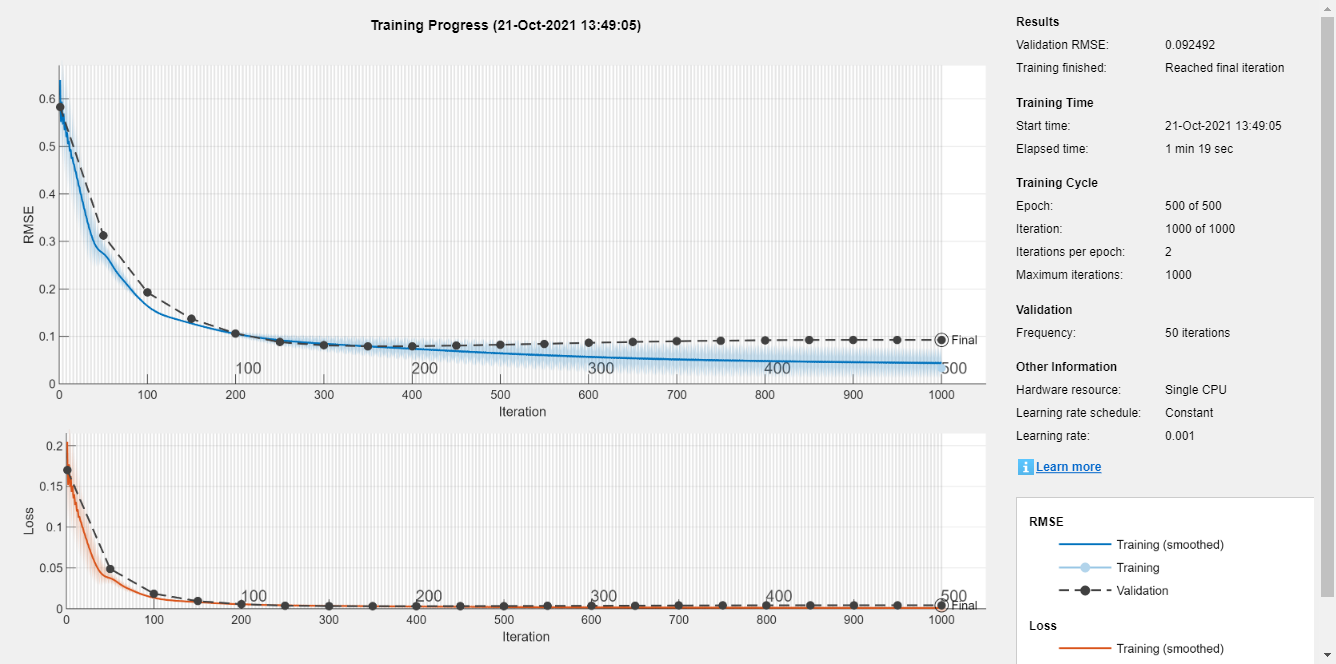

layerCNN1 = [
    imageInputLayer([1, 30]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(Train_Input', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(Train_Output);
tbl = table(cellx);
tbl.cellyB = cellyB;

Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', valtbl);

netCNN1 = trainNetwork(Traintbl, layerCNN1, options);

- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |         0.58 |         0.53 |       0.1672 |       0.1416 |          0.0010 |
|      25 |          50 |       00:00:18 |         0.13 |         0.20 |       0.0079 |       0.0197 |          0.0010 |
|      50 |         100 |       00:00:23 |         0.07 |         0.12 |       0.0025 |       0.0075 |          0.0010 |
|      75 |         150 |       00:00:26 |         0.06 |         0.11 |       0.0019 |   

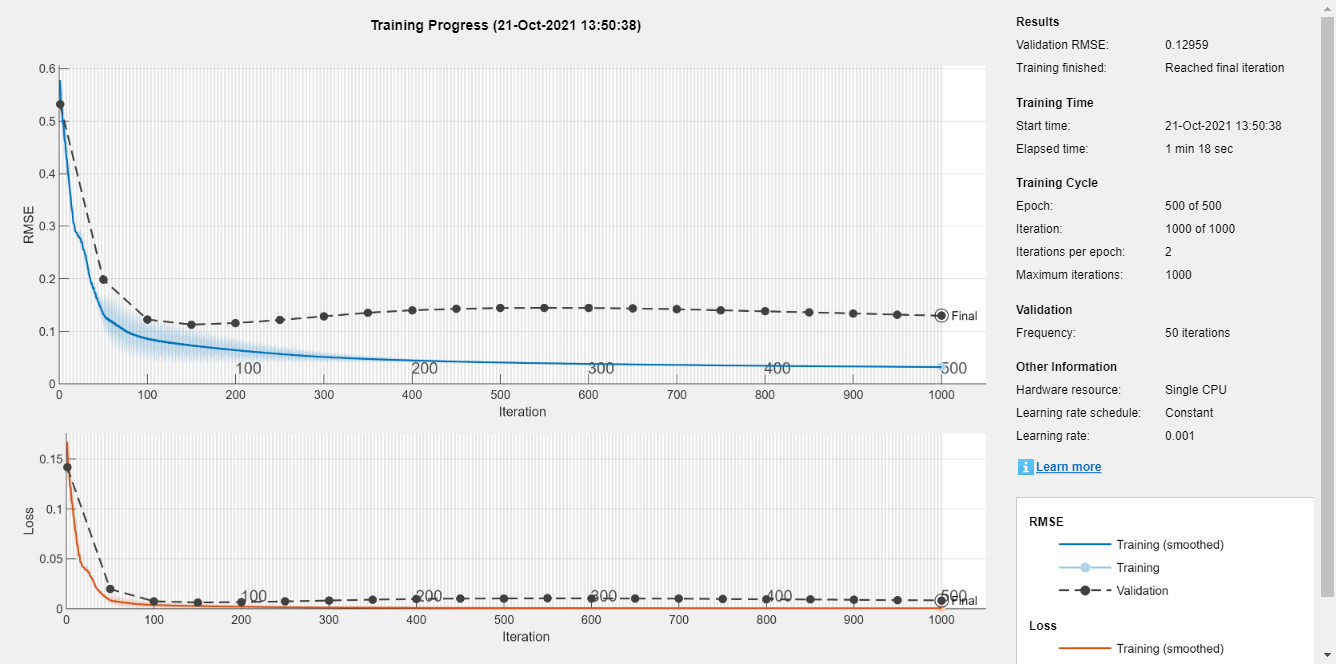

layerCNN2 = [
    imageInputLayer([1, 30]);
    convolution2dLayer([1, 2], 30, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 15, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
netCNN2 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 5 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |         0.54 |         0.50 |       0.1473 |       0.1248 |          0.0010 |
|      25 |          50 |       00:00:20 |         0.16 |         0.17 |       0.0124 |       0.0137 |          0.0010 |
|      50 |         100 |       00:00:24 |         0.14 |         0.12 |       0.0091 |       0.0078 |          0.0010 |
|      75 |         150 |       00:00:29 |         0.12 |         0.09 |       0.0071 |       0.0040 |          0.0010 |
|     10

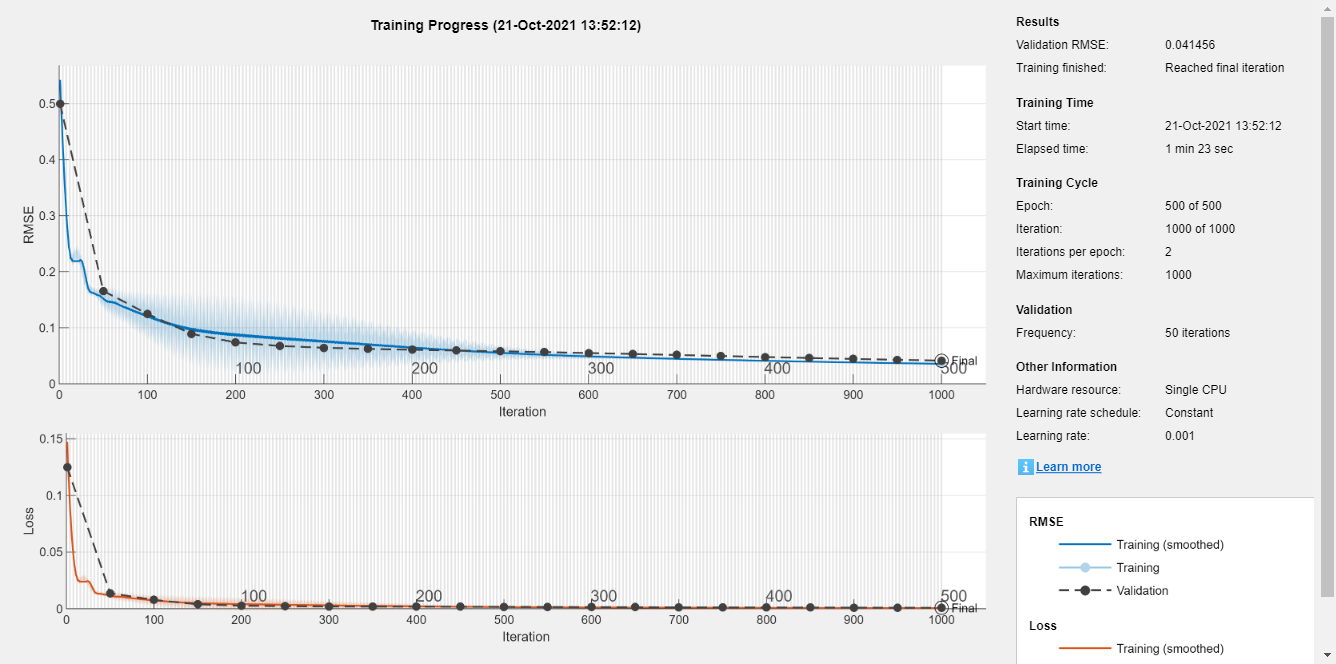

inputSize = 30;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(Train_Input', 1)';
cellyB = num2cell(Train_Output);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',500, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

### Prediciton using each 5 trained model

Make a prediction using trained models

- FNN10

pFNN10 = netFNN10(Train_Input(tr.testInd, :)');

- FNN40

pFNN40 = netFNN40(Train_Input(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(Train_Input(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, 30, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM, num2cell(Train_Input(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

Train_Output = Train_Output(tr.testInd, :)*yr + ym;
pFNN10 = pFNN10*yr+ ym;
pFNN40 = pFNN40*yr + ym;
pCNN1 = pCNN1*yr + ym;
pCNN2 = pCNN2*yr + ym;
pLSTM = pLSTM*yr + ym;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

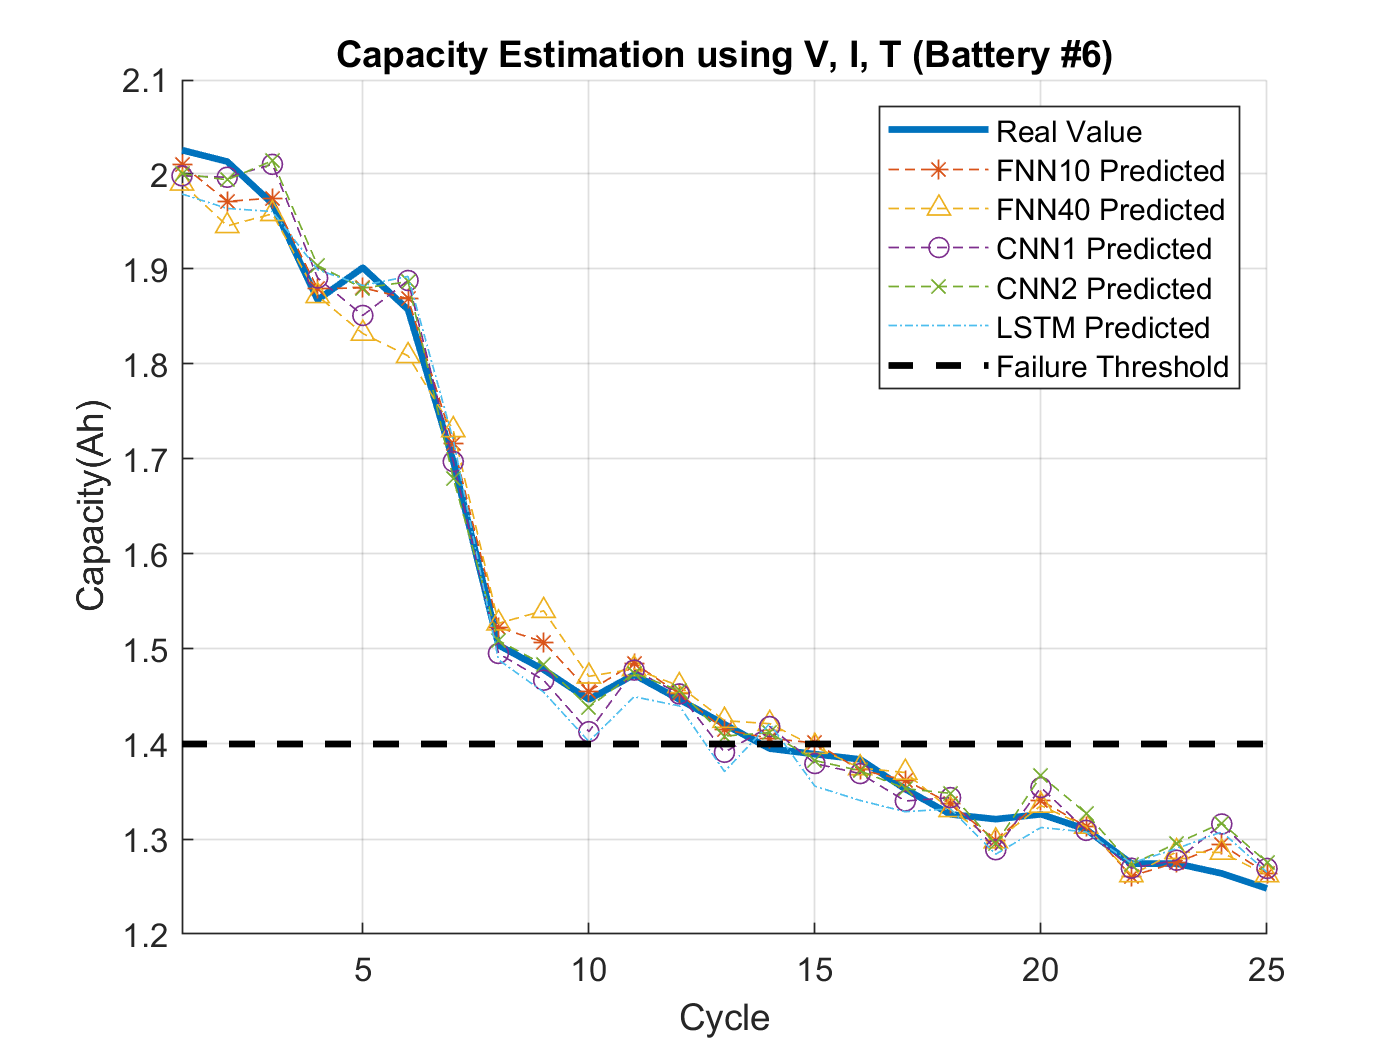

figure, hold on, grid on,
plot(Train_Output, 'linewidth', 2), plot(pFNN10, '*--'), plot(pFNN40, '^--'), plot(pCNN1, 'o--'), plot(pCNN2, 'x--'), plot(pLSTM, '-.')
plot(1:25, 1.4*ones(1, 25),'k--','LineWidth', 2), xlim([1 25])
title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN10 Predicted', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted', 'Failure Threshold')

RMSE

rmse_pFNN10 = sqrt(mean(( Train_Output' - pFNN10 ).^2))

rmse_pFNN10 = 0.0170

rmse_pFNN40 = sqrt(mean(( Train_Output' - pFNN40 ).^2))

rmse_pFNN40 = 0.0298

rmse_pCNN1  = sqrt(mean(( Train_Output' - pCNN1' ).^2))

rmse_pCNN1 = single
0.0248

rmse_pCNN2  = sqrt(mean(( Train_Output' - pCNN2' ).^2))

rmse_pCNN2 = single
0.0236

rmse_pLSTM  = sqrt(mean(( Train_Output' - pLSTM' ).^2))

rmse_pLSTM = single
0.0296

[1] B. Saha and K. Goebel, ``Battery data set,''NASA AMES Prognostics Data Repository, 2007.

[2] Choi, Yohwan, et al. "Machine Learning-Based Lithium-Ion Battery Capacity Estimation Exploiting Multi-Channel Charging Profiles." *IEEE Access* 7 (2019): 75143-75152.

***Copyright 2019 The MathWorks, Inc.***